# Basics of Matrix Operations in MATLAB

This live script introduces fundamental matrix operations, including creating matrices, indexing, slicing, block matrices, stacking, and more.

## Creating Matrices

A = [1, 2; 3, 4; 5, 6];
disp('Matrix A:');
disp(A);
size(A)
fprintf("A has #d colums and #d rows\n", size(A,1), size(A,2));

Reshaping

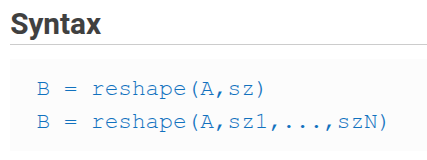

B = 1:8
C = reshape(B, 2, 4)
D = reshape(B, [4, 2])

Identity matrix

I = eye(4);
disp('4x4 Identity matrix I:');
disp(I);

Ones

B = ones(2, 3);
disp('Matrix of ones B:');
disp(B);

## Indexing and Slicing

Access individual elements, rows, and columns of the matrix.

Access element in row 2, column 1 of matrix A

element_23 = A(2, 1);
fprintf('Element at row 2, column 1 of A: %d\n', element_23);

Access the second row

disp('Second row of A:');
row2 = A(2, :)

Access the first column

disp('First column of A:');
col3 = A(:, 1)

Slice the submatrix from rows 2 to 3 and columns 1 to 2

submatrix = A(2:3, 1:2)

## Ensure column-ness or row-ness

rr = 1:5
cc = rr'

Make sure a vector is a column (nx1) - two ways

rr_col = rr(:)
rr_col = reshape(rr, length(rr), 1)
cc_col = cc(:)

Make sure a vector is a row

rr_row = rr(:)'
rr_row = reshape(rr, 1, length(rr))
cc_row = cc(:)'

## Block Matrices: Concatenation and Stacking

Concatenate matrices horizontally and vertically to form block matrices. 

Define two square matrices

C = [1, 2; 3, 4];
D = [5, 6; 7, 8];

Horizontal concatenation (side-by-side)

disp('Horizontal concatenation of C and D:');
H_concat = [C, D]

Vertical concatenation (stacked)

disp('Vertical concatenation of C and D:');
V_concat = [C; D]

## Matrix as a Set of Column Vectors

We can treat each column of a matrix as a separate vector.

Separate columns of A into individual column vectors

disp('Columns of A as separate vectors:');
disp('Column 1:'); 
col1 = A(:, 1)
disp('Last Column:'); 
col2 = A(:, end);

Reconstruct A from its column vectors

disp('Reconstructed A from column vectors:');
A_reconstructed = [col1, col2]

## Transpose of a Block Matrix

Transpose a block matrix to interchange rows and columns.

Transpose of the concatenated matrix H_concat

disp('Transpose of H_concat:');
H_concat_transpose = H_concat'

## Matrix Equivalence

Check if two matrices are equivalent (have the same dimensions and elements).

Compare matrices A and A_reconstructed

disp('Are A and A_reconstructed equivalent?');
isEqual = isequal(A, A_reconstructed)

Use logical operations to confirm element-wise equivalence for same-sized matrices

disp('Element-wise comparison between A and A_reconstructed:');
element_wise_equal = (A == A_reconstructed)
all(A == A_reconstructed)
all(A == A_reconstructed, "all")

Compare different matrices

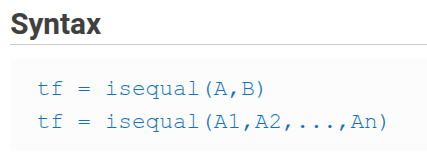

disp('Are C and D equivalent?');
isEqual_CD = isequal(C, D)